## Velocity Estimation For One Single Target

Now that you know how to detect the distance, the next step is to calculate the speed of the target.

For this we need to generate **more Chirps**.

Here is a picture of what I mean.

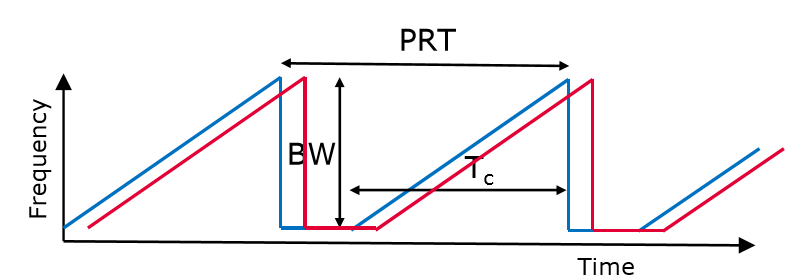

- The image shows 2 Chirps and a half.

- However, we'll be using about 64 to 128 chirps in our model. (I'll explain later why these numbers)

- The blue line represents the transmitted signal and the red line the received signal.

- The letters BW stands for Bandwidth and Tc for the Chirp Time. (You should already be familiar with these terms)

- You can also see a new Parameter **PRT. **(Chirp Repetition Time)

- This last parameter is the time between each chirp including the idle time.

You can think of this as taking a blast of pictures.

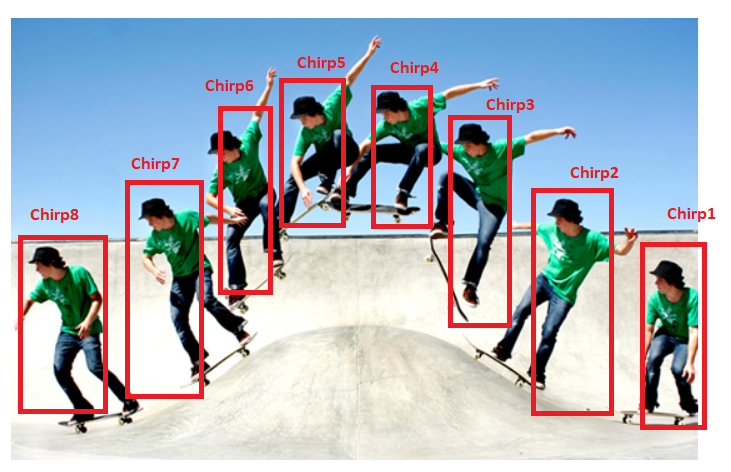

However, since the chirp are so fast we would actually see the following.

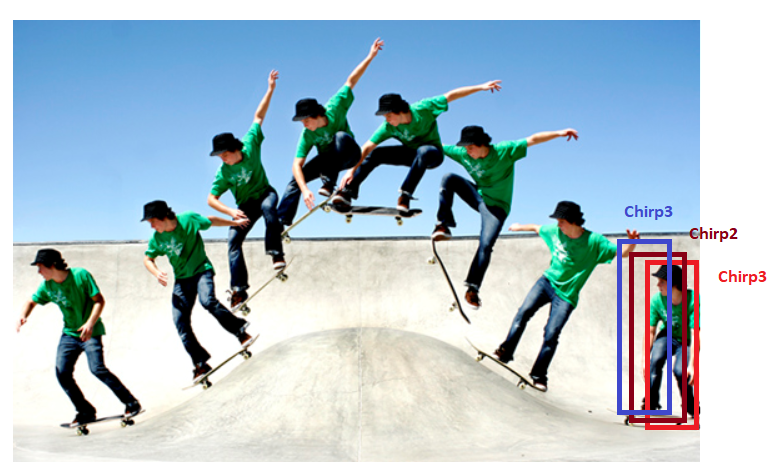

- It seems that the target is not moving at all... However it is! 

- What happens is that between each chirp we send, the target distance changes very little. (maybe millimeters)

- Here is where doppler plays an important role in determining speed!

Because of doppler we will obtain a **change in the phase** of our received signal. Look at the following image.

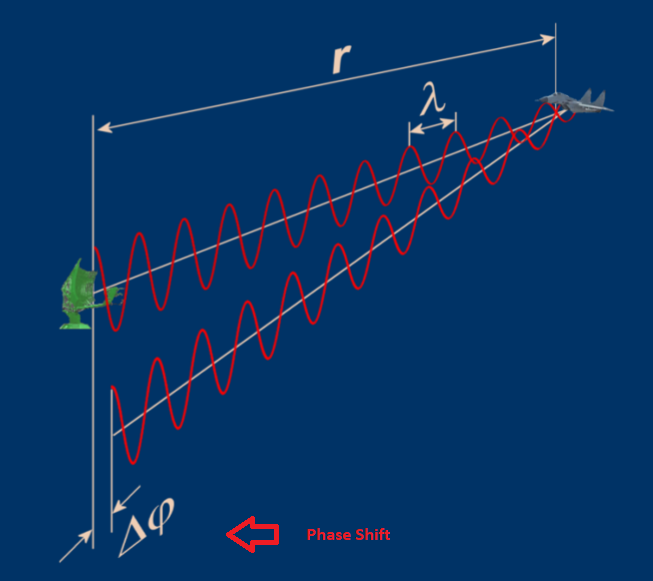

- So basically if we send multiple chirps we will be able to see a proportional change in phase.

- We will use the first chirp as a reference.

- For example:Our first chirp has a 0 degree phase, the second has a 10 degree phase, the third has a 20 degree phase, the fourth has a 30 degree phase and so on. 

- We can see that the phase changes by 10 degrees with each chirp.

- And it's exactly this changing phase that's going to help us determine the speed of the target.

- The faster the Phase Shift, the faster the moving target.

The following image summarizes what I just mentioned.

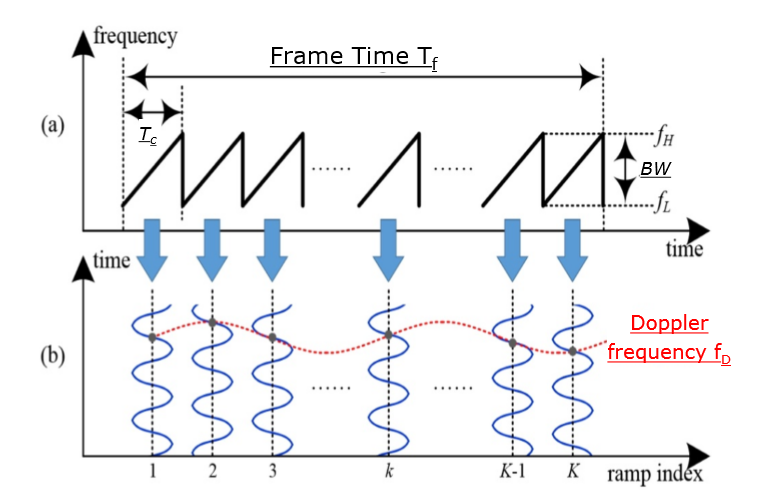

## Plotting Multiple Chirps

Like the previous exercise we have to define our parameters.

Here we will be using the same setting as before.

**Setting Up The Radar Parameters**

Carrier_Frequency      = 6e9;                               %Carrier Frequency in [Hz]
c                      = 3e8;                               %Speed of light in [m/s]
Chirp_Duration         = 10e-6;                              %This would be my Tc in [s]
Bandwidth              = 50e6;                              %Basically how much increase the frequency (in this case from 6GHz to 6.05 GHz)
Sweep_Slope            = Bandwidth/Chirp_Duration;          %How much increment the frequency with time
Sampling_Frequency     =  2*Bandwidth;                      %Our Sampling Frequency should be at least twice the Bandwidth in order to reproduce a good signal

**Setting up the Frequency Modulated Function**

We will leave the same values but this time we are increasing the number of chirps to 128

Chirp_Repetition_Frequency  = 1/Chirp_Duration;
Sample_Time                 = 1/Sampling_Frequency;                                %This determine how much will incresea the time in the x_achse (0.000001 s each time)
Num_Of_Chirps               = 128;                                                 %How many chirps do we want
Total_Measurement_Time      = Num_Of_Chirps*Chirp_Duration;                        %Total amount of time while simulating
Time_Grid                   = 0:Sample_Time: Total_Measurement_Time-Sample_Time;   %This setup the boundaries of the x_achse (For example from 0s to 1s: 0s, 0.0001, 0.0002, 0.0003.... 1.000s) (For the whole Measurement Time)
Chirp_Time_Grid             = 0:Sample_Time:Chirp_Duration-Sample_Time;            %Time Grid for one single Chirp

Frequency_Modulated_Signal  = exp(1i*2*pi*Carrier_Frequency*Chirp_Time_Grid +1i*pi*(Sweep_Slope).*(Chirp_Time_Grid.^2)); %Voila! Our modulated signal in form of a Chirp

**Creating Our Target Position**

Let's start with a simple example where we only have **one target**.

Target1_Position = 100;                        %in [m]

**Creating our Target Velocity**

Target1_Velocity = 0*1000/3600;              %in [m/s] (Notice the factor 1000/3600 which represent the conversion from km/h to m/s)

**Creating Our Time Delay For The Received Signal**

delta1 = 2*Target1_Position/c;                  %in [s]

**Creating Our Doppler Frequency **

Here we have to calculate our doppler frequency depending on the speed of our target.

For this we have to take into account the doppler equation:

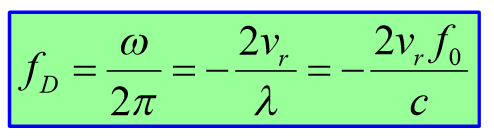

lambda = c/Carrier_Frequency;                   %Wavelength in [m]
Frequency_Dop1 = 2*Target1_Velocity/lambda;     %Doppler Frequency Cprresponding to the Velocity of the Target in [m/s]

As you can see** the higher the speed** of the target $v_r$, **the higher the doppler frequency **$f_d$.

Once we've finished setting our variables, it's time to start the simulation.

## Starting The Simulation Process

**Creating our Transmitted Signal**

%Pre-Allocating Space
Transmitted_Signal       = zeros(Num_Of_Chirps, length(Time_Grid));

%Adding All The Chirps In A Single Frame
for Chirp_Count = 1:Num_Of_Chirps
    if Chirp_Count == 1
         Transmitted_Signal = Frequency_Modulated_Signal;
    else
         Transmitted_Signal(Chirp_Count,:) = Frequency_Modulated_Signal;
    end
end
    if Num_Of_Chirps>1
        New_Frequency_Modulated_Trans = Transmitted_Signal.';
        Transmitted_Signal = reshape(New_Frequency_Modulated_Trans,[1,numel(New_Frequency_Modulated_Trans)]);
    end
    

**Plotting The Spectrogram To check Our Chirps**

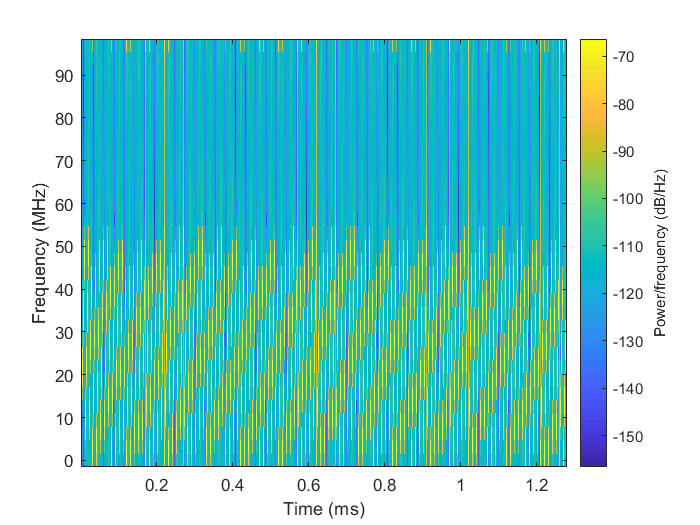

spectrogram(Transmitted_Signal,32,16,32,Sampling_Frequency, 'yaxis'); %Plotting the Spectrogram

**Creating Our Received Signals In Form Of Multiple Chirps**

%Pre-Allocating Space
Transmitted_Signal_Chirp = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps); % The reason I create another transmitted signal is to rearrange the rows and column to facilitate the calculation in general
Received_Signal = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps);          % Creating space for easy computing

%Creating our Chirps but in a different matrix shape
for Count_Of_Chirps = 1 :Num_Of_Chirps
    Transmitted_Signal_Chirp(:,Count_Of_Chirps) = [New_Frequency_Modulated_Trans(:,Count_Of_Chirps); zeros(length(Frequency_Modulated_Signal),1)]; 
end

%Adding The Time Delay To Each Chirp
for Count_Of_Chirps = 1: Num_Of_Chirps
    Received_Signal(:,Count_Of_Chirps) = circshift(Transmitted_Signal_Chirp(:,Count_Of_Chirps), find(Time_Grid>delta1, 1));
end

%Adding the Doppler Frequency To Each Chirp
for Count_Of_Chirps = 1: Num_Of_Chirps
    Received_Signal(:,Count_Of_Chirps) = Received_Signal(:,Count_Of_Chirps).*[exp(1i*2*pi*Frequency_Dop1.*(Chirp_Time_Grid + Count_Of_Chirps*Chirp_Duration)).'; zeros(length(Chirp_Time_Grid), 1)];
end

**Getting The Beat Frequency For Each Chirp**

%Pre-Allocating Space For The Mixer Result
Beat_Chirp = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps);

%Multiplying Our Transmitted Signal With Each Single Chirp (Mixer Process)
for Count_Of_Chirps = 1: Num_Of_Chirps 
    Beat_Chirp(:,Count_Of_Chirps) = Transmitted_Signal_Chirp(:,1).*conj(Received_Signal(:,Count_Of_Chirps));
end


**Applying The Fast Fourier Transform**

%Pre-Allocating Space for the 2D-FFT
VerticalFFT = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps);                %This Represents The Pre-Allocated Space For The 1D-FFT
HorizontalFFT = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps);              %This Represents The Pre-Allocated Space For The 2D-FFT

%Applying The Fast Fourier Transform Along The Vertical Axis For Each Chirp
for Chirp_Count =1 : Num_Of_Chirps 
    VerticalFFT(:,Chirp_Count) = fft(Beat_Chirp(:,Chirp_Count));                        %This represents the 1D-FFT for Computing The Range
end

%Applying The Fast Fourier Transform Along The Horizontal Axis
for Frequency_Bin_Count=1:length(VerticalFFT(:,1))
    HorizontalFFT(Frequency_Bin_Count,:) = fft(VerticalFFT(Frequency_Bin_Count,:));    %This represents the 2D-FFT for Computing The Velocity
end

- Here we are doing exactly the same thing as in the previous range estimation exercise.

- The only difference is that we're now applying FFT to each of the chirp samples (vertical-axis).

- This will determine the beat frequency to determine the distance.

- Once we've done this we'll apply the fft along the horizontal axis.

- This will determine the linear phase change for calculating the velocity

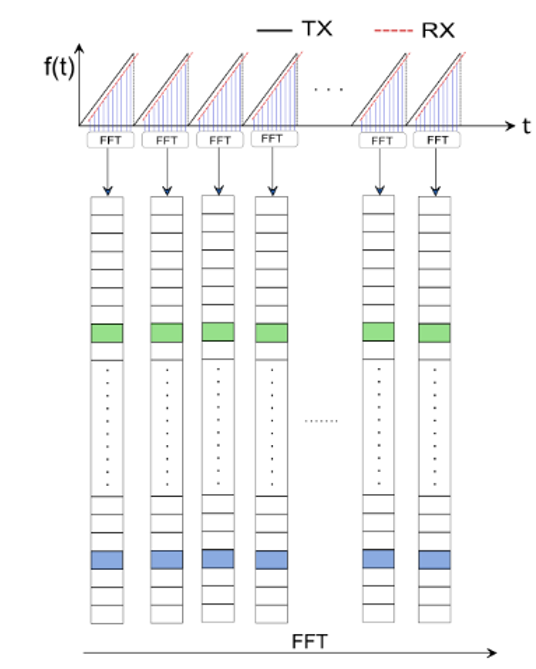

**Plotting the Frequency Range Spectrum**

This step is not necessary but serves to verify that our distance matches.

So we can compare more quickly if everything is in order.

**Converting the y-axis in Power**

Mag_X             = abs(VerticalFFT);                              %Absolute value for the fft
Power             = 20*log10(Mag_X);       

**Converting Frequency Bins into distance in [m]**

Frequency_bins      = 0:length(Mag_X(:,1))-1;                                   %Creating a Vector Representing The Frequency Bins. Notice we begin from 0! Therefore we subtract 1 at the end.
Frequency_Range     = Frequency_bins*Sampling_Frequency/length(Mag_X(:,1));     %Calculating the Frequency That is represented by each Frequency Bin
Range               = Frequency_Range*Chirp_Duration*c/(2*Bandwidth);           %Using The Range Formula Equation

**Plotting The Frequency range Spectrum one more time**

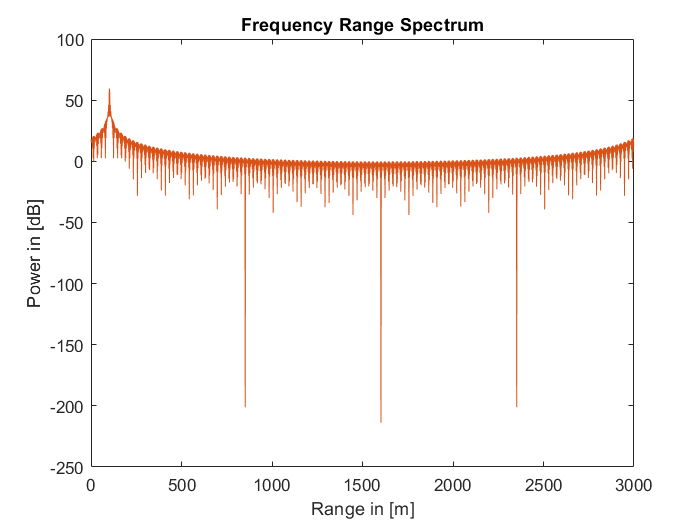

figure;
plot(Range,Power);                      %We are plotting The Range along the x-axis and the Power along the y-axis
title('Frequency Range Spectrum');
xlabel('Range in [m]');
ylabel('Power in [dB]');

**Shift Zero-Frequency Component To Center Of Spectrum**

Since our target can move towards us as well as away from us we'll get two types of frequencies.

These can be negative as well as positive.

That's why we're going to put our zero right in the middle of the diagram.

X_Shift = fftshift(HorizontalFFT,2);                %Centering the FFT Since we can have "Positive" and "Negative" Frequencies. This just represent the direction of the moving target. Fdado

**Getting The Absolute Value**

Mag_X_Shift = abs(X_Shift);                         

**Converting The x-axis Into Velocities**

Frequency_Vel = (-Chirp_Repetition_Frequency/2:Chirp_Repetition_Frequency/Num_Of_Chirps:Chirp_Repetition_Frequency/2-Chirp_Repetition_Frequency/Num_Of_Chirps).*(-1);       %zero-centered frequency range
Velocity = (Frequency_Vel*lambda/2).*(3600/1000);

**Plotting The velocity Estimation**

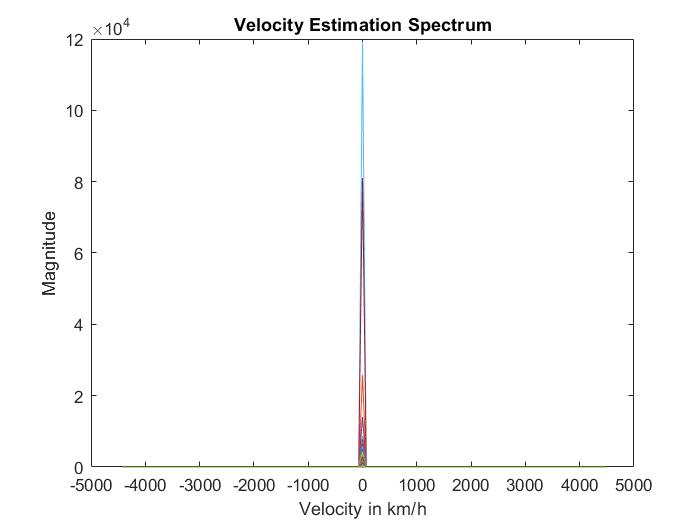

figure;
plot(Velocity,Mag_X_Shift);
title('Velocity Estimation Spectrum');
xlabel('Velocity in km/h');
ylabel('Magnitude');

- If an object doesn't move at all, you'll see it right in the center of the plot.

- That means that it would be a stationary target and would not present any kind of doppler frequency

**Doppler-Range-Image**

We're going to combine both range and speed in a single image.

The x-axis represents the speed and the y-axis the Range.

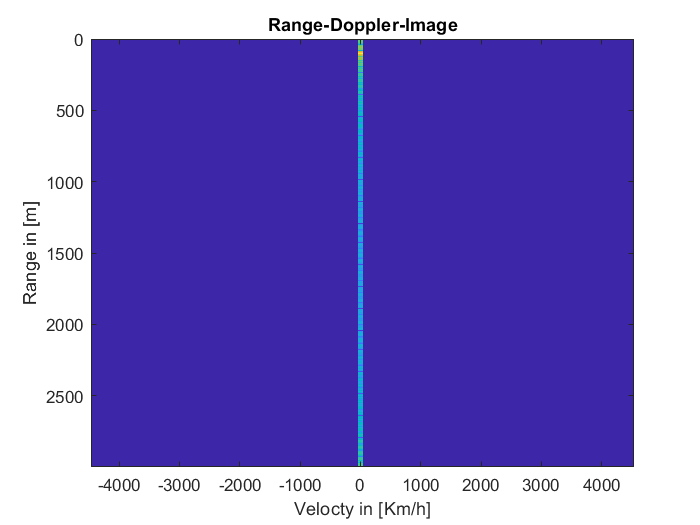

figure;
imagesc(Velocity,Range,100*log(1+Mag_X_Shift));
title('Range-Doppler-Image');
xlabel('Velocty in [Km/h]');
ylabel('Range in [m]');

The x-axis represents the Velocity in km/h and the y-axis the Range.

The point that jumps out with a clear color is our Target.

If you zoom in on the image you can see the position and speed of the target more accurately.

Here's the same plot but in 3D

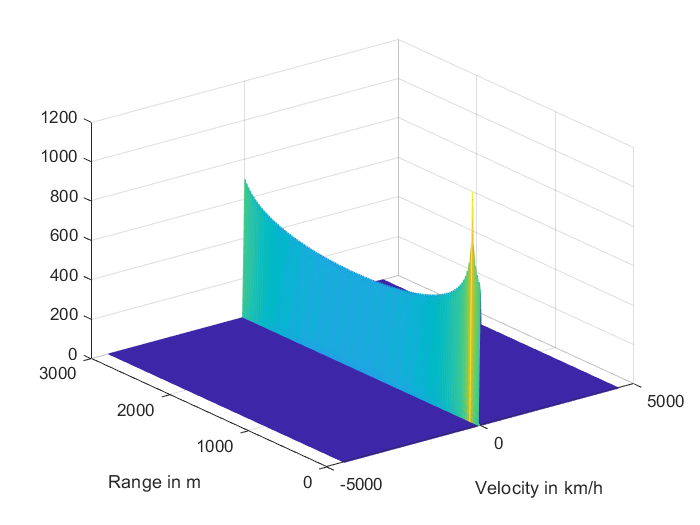

[V R] = meshgrid(Velocity, Range);
surf(V,R,100*log(1+Mag_X_Shift),'EdgeColor','flat');
xlabel('Velocity in km/h');
ylabel('Range in m');

As you can see the brigth peak shows or target.

## Playing Instructions

Now it's your turn to play a little!

But I want you to consider again the following formulas and questions.

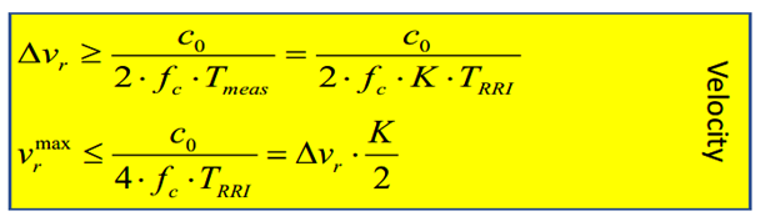

$\Delta v_r$      - Velocity Resolution

${V^{\mathrm{max}} }_r$   - maximum Radial Speed

$f_c$        - Carrier Frequency

$c_0$       - Speed of Light

$T_{\mathrm{meas}}$  - Measurement Time (Observation Time)

$T_{\mathrm{RRI}}$   - Chirp Repetition Time

$K$      - Number Of Chirps

**Question: ** What happens if I reduce my Chirp time?

**Question**: What happens if I choose a high operating frequency?

**Question:** How many Chirps do we want and why increasing the number of chirps is important?

**Question**: How can I improve my Velocity Resolution?

**Now I want you to do the next steps!**

    1.Set up the number of chirps up to 128.

    2.Choose a distance your target that is not higher than 2000 m

    3.Choose a velocity between -4000 km/h and 4000 km/h

    4.Simulate and Plot

    5.Analyze the Range-Doppler Image. Does it show what is supposed to show?

    6. Increase the velocity above 5000 km/h

    7. Is it okay what is happening? if not why is that happening and how can we fix it? (Take a look at the Equation on the top)